# Lagrange interpolation

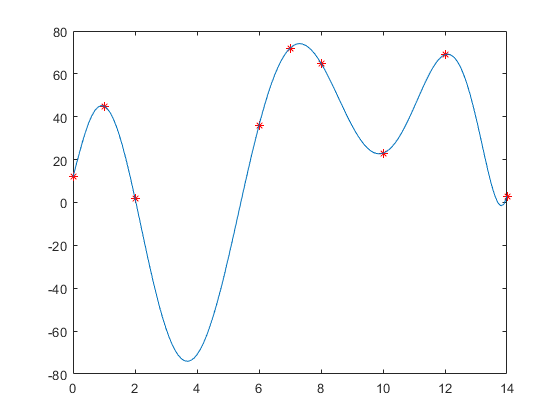

n = 9

t=[0:0.1:14];
x =[0 1 2 6 7 8 10 12 14];
y = [12 45 2 36 72 65 23 69 3];
plot(x,y,'r*');hold on %標出所有的(x,y)座標點
plot(t,LagrangePol(t,x,y)); % 畫出點(x1,y1)到點(x2,y2)之間的Lagrange曲線

function y = LagrangePol(x,px,py)
    n = size(px,2) 
    % m = size(X,dim);%返回矩陣的行數或列數，dim=1返回行數，dim=2返回列數
    L=ones(n,size(x,2)); % ones(n1,n2)　值一n1xn2矩陣，元素值為1
    for i=1:n
        for j=1:n
            if (i~=j)
                L(i,:) = L(i,:).*(x-px(j))/(px(i)-px(j)); 
                % 計算px之間預測的相對誤差，並更新Lagrange equation coefficient
            end
        end
    end
    y = 0;
    for i=1:n
        y = y + py(i)*L(i,:); % 計算對於每一個y的相對輸出
    end
end